% A demo script that demonstrates how to process a single video file using
% OpenFace and extract and visualize all of the features

clear

openface_path = "C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\code\\OpenFace_2.2.0_win_x64\\"

openface_path = "C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\code\\OpenFace_2.2.0_win_x64\\"

executable = openface_path + "FeatureExtraction.exe";
in_dir = "C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\vol04\\face-center\\"

in_dir = "C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\vol04\\face-center\\"

out_dir = "C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\vol04\\face-features\\"

out_dir = "C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\vol04\\face-features\\"



S = dir(fullfile(in_dir,'*'));
N = setdiff({S([S.isdir]).name},{'.','..'}); % list of subfolders of D.
for ii = 1:numel(N)
    T = dir(fullfile(in_dir,N{ii},'*')); % improve by specifying the file extension.
    C = setdiff({T([T.isdir]).name},{'.','..'});
    for jj = 1:numel(C)
        in = fullfile(in_dir, N{ii}, C{jj}); % improve by specifying the file extension.
        out = fullfile(out_dir, N{ii}, C{jj}); % improve by specifying the file extension.
        
        command = sprintf('%s -fdir "%s" -out_dir "%s" -verbose', executable, in, out);
        if(isunix)
            unix(command);
        else
            dos(command);
        end
    end
end

Reading the landmark detector/tracker from: C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\code\\OpenFace_2.2.0_win_x64\model/main_ceclm_general.txt 
Reading the landmark detector module from: C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\code\\OpenFace_2.2.0_win_x64\model\cen_general.txt 
Reading the PDM module from: C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\code\\OpenFace_2.2.0_win_x64\model\pdms/In-the-wild_aligned_PDM_68.txt....Done 
Reading the Triangulations module from: C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\code\\OpenFace_2.2.0_win_x64\model\tris_68.txt....Done 
Reading the intensity CEN patch experts from: C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\code\\OpenFace_2.2.0_win_x64\model\patch_experts/cen_patches_0.25_of.dat....Done 
Reading the intensity CEN patch experts from: C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\code\\OpenFace_2.2.0_win_x64\model\patch_experts/cen_patches_0.35_of.dat....Done 
Reading the intensity CEN patch experts from: C:\\Users\\ASABUNCUOGLU13\\Docu

## Demonstrating reading the output files

% Most of the features will be in the csv file in the output directory with
% the same name as the input file
[~,name,~] = fileparts(in_dir);
output_csv = sprintf('%s/%s.csv', output_dir, name);

% First read in the column names, to know which columns to read for
% particular features
tab = readtable(output_csv);

Error using readtable
Unable to find or open 'C:\\Users\\ASABUNCUOGLU13\\Documents\\data\\vol02\\td-slices-cansu\\face-features\\/frames-.csv'. Check the path and filename or file
permissions.

column_names = tab.Properties.VariableNames;

% Read all of the data
all_params  = dlmread(output_csv, ',', 1, 0);

% This indicates which frames were succesfully tracked

% Find which column contains success of tracking data and timestamp data
valid_ind = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'success'));
frame_ind = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'frame'));

% Extract tracking success data and only read those frame
valid_frames = logical(all_params(:,valid_ind));

% Get the timestamp data
frame_nums = all_params(valid_frames, frame_ind);

## Finding which header line starts with p_ (basically model params)

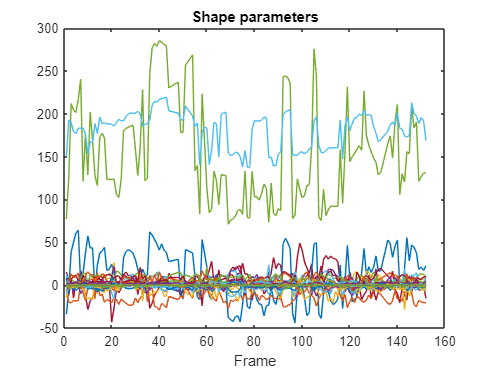

shape_inds = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'p_'));

% Output rigid (first 6) and non-rigid shape parameters
shape_params  = all_params(valid_frames, shape_inds);

figure
plot(frame_nums, shape_params);
title('Shape parameters');
xlabel('Frame');

## Demonstrate 2D landmarks

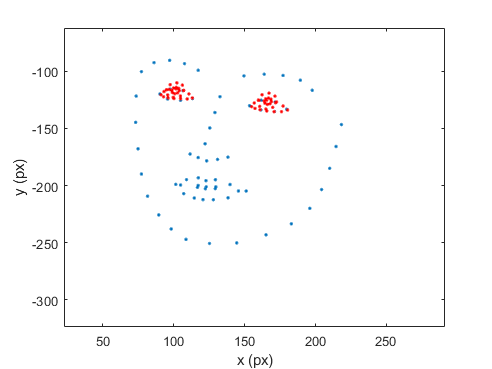

landmark_inds_x = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'x_'));
landmark_inds_y = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'y_'));

xs = all_params(valid_frames, landmark_inds_x);
ys = all_params(valid_frames, landmark_inds_y);

eye_landmark_inds_x = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'eye_lmk_x_'));
eye_landmark_inds_y = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'eye_lmk_y_'));

eye_xs = all_params(valid_frames, eye_landmark_inds_x);
eye_ys = all_params(valid_frames, eye_landmark_inds_y);

figure

for j = 1:size(xs,1)
    plot(xs(j,:), -ys(j,:), '.');
    hold on;
    plot(eye_xs(j,:), -eye_ys(j,:), '.r');
    hold off;
    
    xlim([min(xs(1,:)) * 0.5, max(xs(2,:))*1.4]);
    ylim([min(-ys(1,:)) * 1.4, max(-ys(2,:))*0.5]);
    xlabel('x (px)');
    ylabel('y (px)');
    drawnow
end

## Demonstrate 3D landmarks

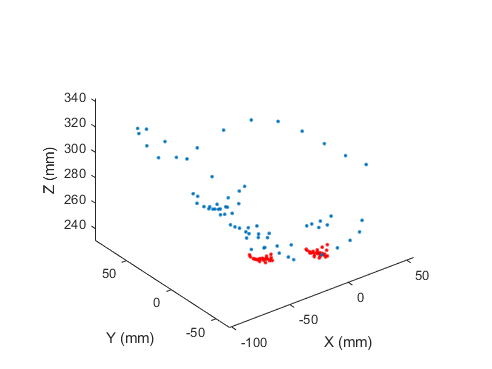

landmark_inds_x = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'X_'));
landmark_inds_y = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'Y_'));
landmark_inds_z = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'Z_'));

xs = all_params(valid_frames, landmark_inds_x);
ys = all_params(valid_frames, landmark_inds_y);
zs = all_params(valid_frames, landmark_inds_z);

eye_landmark_inds_x = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'eye_lmk_X_'));
eye_landmark_inds_y = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'eye_lmk_Y_'));
eye_landmark_inds_z = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'eye_lmk_Z_'));

eye_xs = all_params(valid_frames, eye_landmark_inds_x);
eye_ys = all_params(valid_frames, eye_landmark_inds_y);
eye_zs = all_params(valid_frames, eye_landmark_inds_z);

figure
for j = 1:size(xs,1)
    plot3(xs(j,:), ys(j,:), zs(j,:), '.');axis equal;
    hold on;
    plot3(eye_xs(j,:), eye_ys(j,:), eye_zs(j,:), '.r');
    hold off;
    xlabel('X (mm)');
    ylabel('Y (mm)');
    zlabel('Z (mm)');
    drawnow
end

## Demonstrate AUs

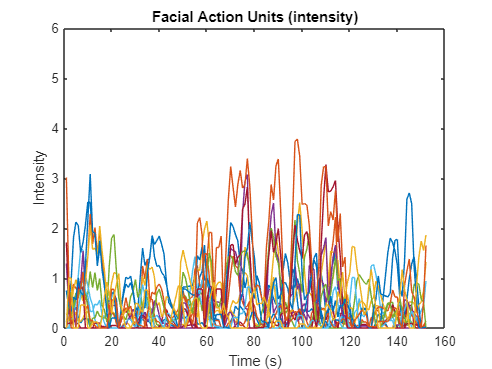

au_reg_inds = cellfun(@(x) ~isempty(x) && x==5, strfind(column_names, '_r'));

aus = all_params(valid_frames, au_reg_inds);
figure
plot(frame_nums, aus);
title('Facial Action Units (intensity)');
xlabel('Time (s)');
ylabel('Intensity');
ylim([0,6]);

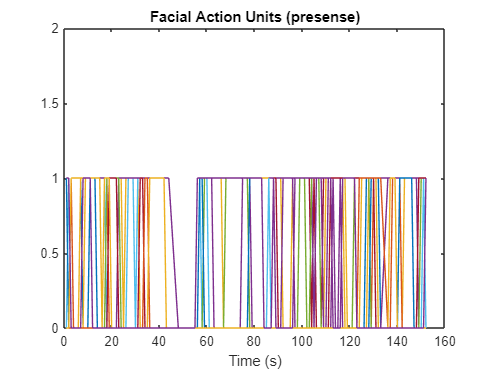


au_class_inds = cellfun(@(x) ~isempty(x) && x==5, strfind(column_names, '_c'));

aus = all_params(valid_frames, au_class_inds);
figure
plot(frame_nums, aus);
title('Facial Action Units (presense)');
xlabel('Time (s)');
ylim([0,2]);

## Demo pose

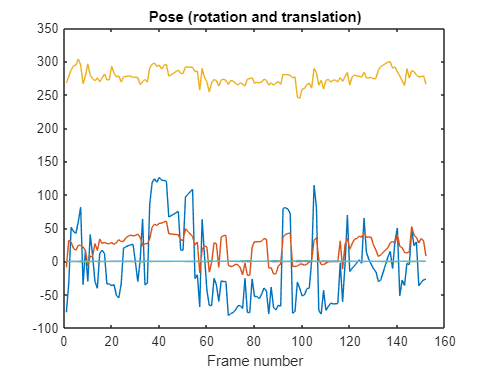

pose_inds = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'pose_'));

pose = all_params(valid_frames, pose_inds);
figure
plot(frame_nums, pose);
title('Pose (rotation and translation)');
xlabel('Frame number');

## Demo gaze

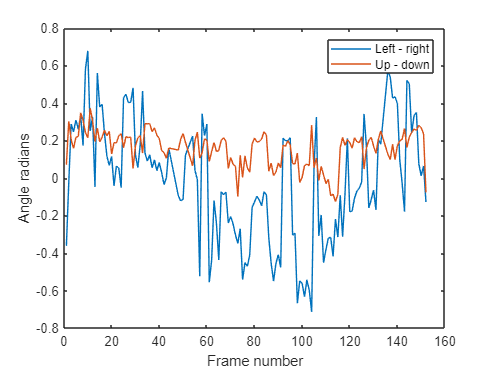

gaze_inds = cellfun(@(x) ~isempty(x) && x==1, strfind(column_names, 'gaze_angle'));

% Read gaze (x,y,z) for one eye and (x,y,z) for another
gaze = all_params(valid_frames, gaze_inds);

plot(frame_nums, gaze(:,1), 'DisplayName', 'Left - right');
hold on;
plot(frame_nums, gaze(:,2), 'DisplayName', 'Up - down');
xlabel('Frame number') % x-axis label
ylabel('Angle radians') % y-axis label
legend('show');
hold off;

## Output HOG files

output_hog_file = sprintf('%s/%s.hog', output_dir, name);
[hog_data, valid_inds] = Read_HOG_file(output_hog_file);

## Output aligned images

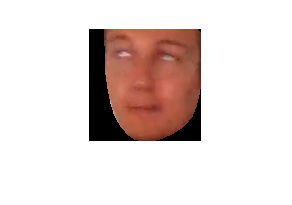

output_aligned_dir = sprintf('%s/%s_aligned/', output_dir, name);
img_files = dir([output_aligned_dir, '/*.bmp']);
imgs = cell(numel(img_files, 1));
for i=1:numel(img_files)
    imgs{i} = imread([ output_aligned_dir, '/', img_files(i).name]);
    imshow(imgs{i})
    drawnow
end